%SET PARAMETERS:
H = 0.1;
l2 = 0.2;
l3 = 0.1;
params = [H,l2,l3];

%VARIABLES TO PLAY WITH: T, n, profile
PROFILE = 'trapezoidal';
T = 2;
n = 1000;

% INITIALIZING TRAJECTORY
x_init = [0.1, 0.2, 0.35]';
x_fin = [0.3, -0.1, 0.15]';

x = x_plan(PROFILE, T, n, x_init, x_fin);
v = v_plan(PROFILE, T, n, x_init, x_fin);
a = a_plan(PROFILE, T, n, x_init, x_fin);

q = q_plan(x,[1,1], params);

q_dot = q_dot_plan(q, v, T, 'analytical', params);
q_dot_NUM = q_dot_plan(q, v, T, 'numerical', params);

q_dot2 = q_dot2_plan(q, q_dot, a, T, 'analytical', params);
q_dot2_NUM = q_dot2_plan(q, q_dot, a, T, 'numerical', params);

t = linspace(0, T, n);

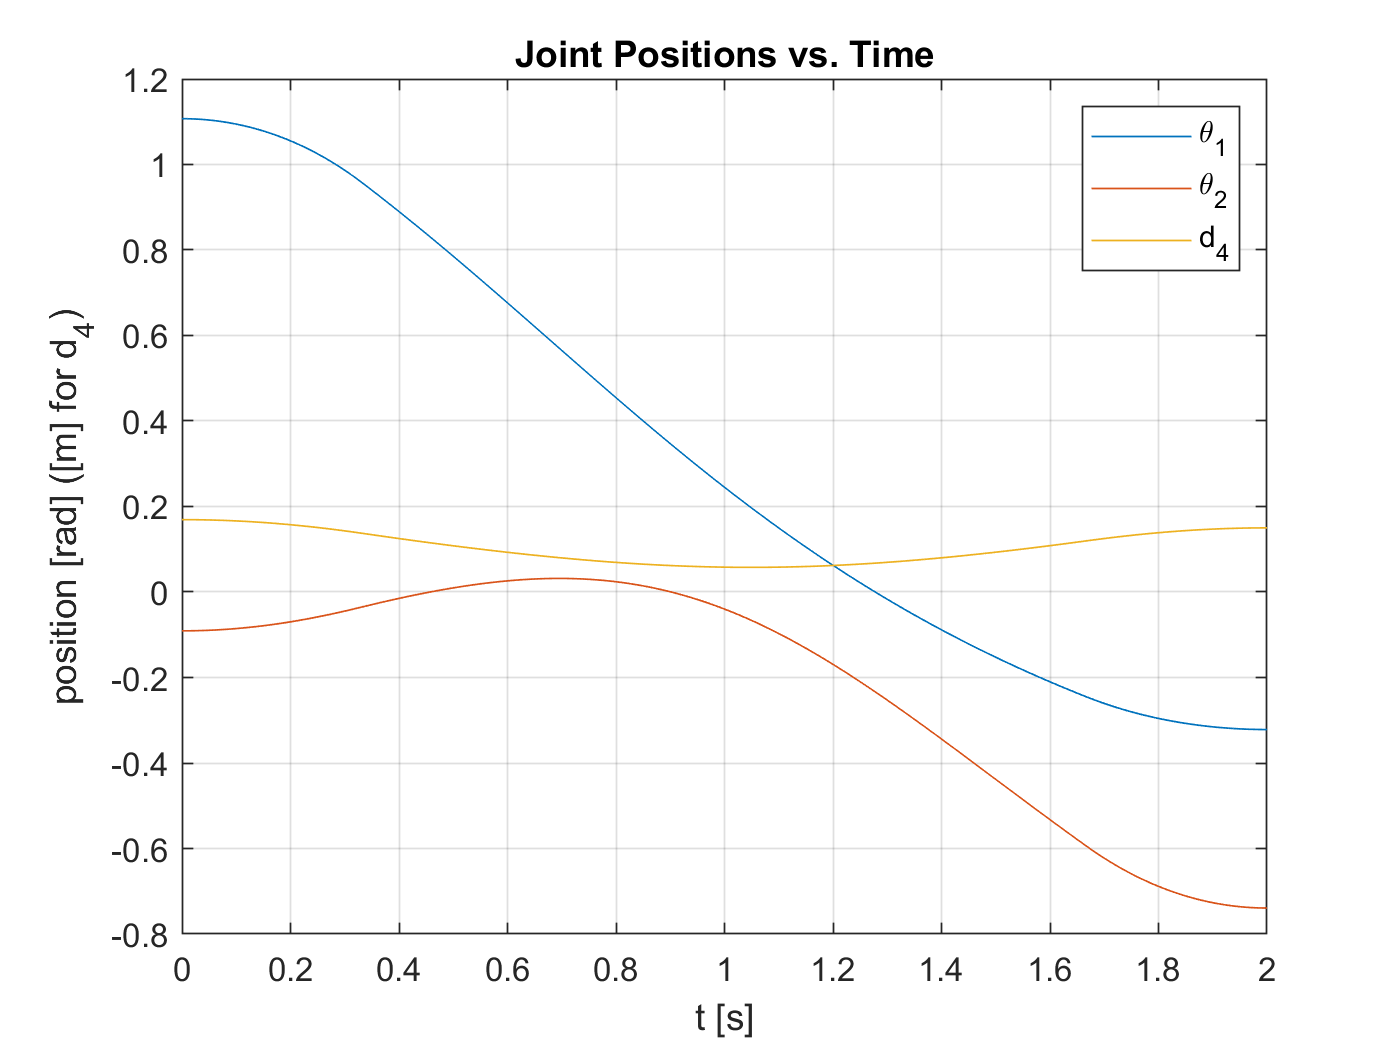

% PLOT OF JOINT POSITIONS W.R.T TIME
plot(t,q(1,:))
hold on
plot(t,q(2,:))
plot(t,q(3,:))
hold off
legend('\theta_1', '\theta_2', 'd_4')
grid on
title('Joint Positions vs. Time')
xlabel('t [s]')
ylabel('position [rad] ([m] for d_4)')

% plot(t,q_dot(1,:), '--');
% hold on
% plot(t,q_dot_NUM(1,:), '--');
% 
% legends = {'$\dot{\theta_1}$', '$\dot{\theta_2}$', '$\dot{d_4}$'};
% legends = string(legends)
% legends(1)
% legends(2)
% hl = legend(legends(1), legends(2));
% set(hl, 'Interpreter', 'latex');
% hold off

% % PLOTS OF JOINT VELOCITIES W.R.T TIME
% 
% legends = {'$\dot{\theta_1}$ (analytical)', '$\dot{\theta_1}$ (numerical)';
% '$\dot{\theta_2}$ (analytical)', '$\dot{\theta_2}$ (numerical)';
% '$\dot{d_4}$ (analytical)', '$\dot{d_4}$ (numerical)'};
% legends = string(legends);
% for i=1:3
%     subplot(3,1,i)
%     plot(t, q_dot(i,:))
%     hold on;
%     plot(t,q_dot_NUM(i,:), '--');
%     xlabel('t [s]')
%     hl = legend(legends(i,1), legends(i,2));
%     set(hl, 'Interpreter', 'latex');
% end
% hold off;

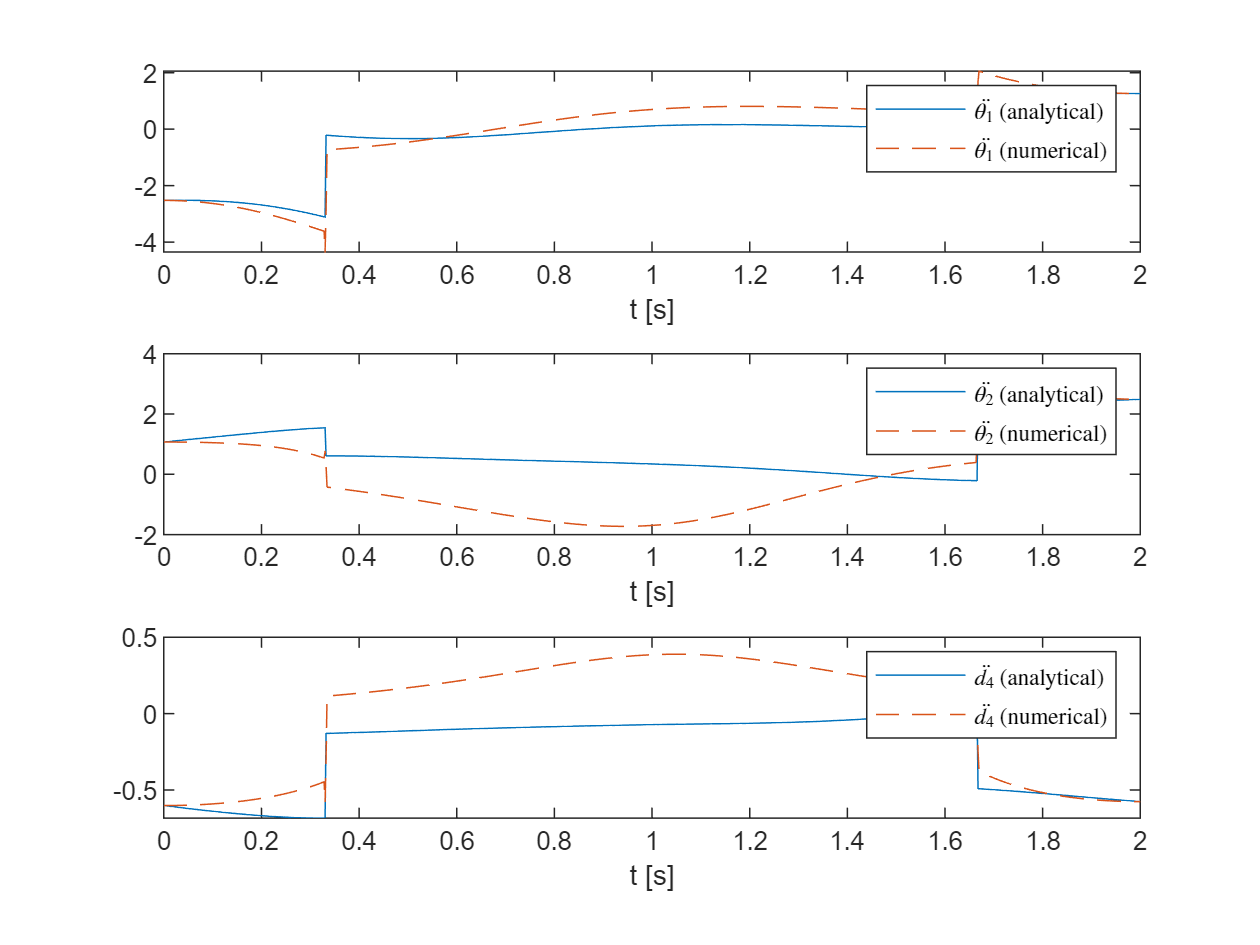

% PLOTS OF JOINT ACCELERATIONS W.R.T TIME

legends = {'$\ddot{\theta_1}$ (analytical)', '$\ddot{\theta_1}$ (numerical)';
'$\ddot{\theta_2}$ (analytical)', '$\ddot{\theta_2}$ (numerical)';
'$\ddot{d_4}$ (analytical)', '$\ddot{d_4}$ (numerical)'};
legends = string(legends);

for i=1:3
    subplot(3,1,i)
    plot(t, q_dot2(i,:))
    hold on;
    plot(t,q_dot2_NUM(i,:), '--');
    xlabel('t [s]')
    hl = legend(legends(i,1), legends(i,2));
    set(hl, 'Interpreter', 'latex');
end